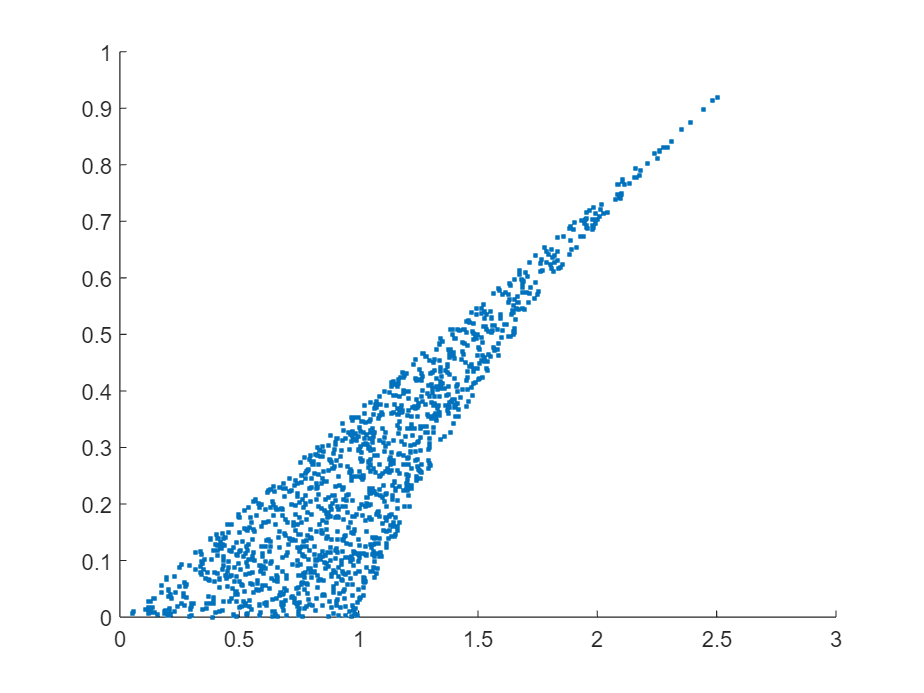

clf
n = 1e4;
X = rand(n,1)*exp(1);
Y = rand(n,1);
Shape = Y>log(X)&Y<X/exp(1);
scatter(X(Shape),Y(Shape),'.')

P = sum(Shape)/n

P =    0.131800000000000


Since points (x,y) are uniformally distributed on [0,e]x[0,1], whose area is e, the area of the shape should be P*e.

clc
I = simplify(int(x/exp(sym(1))-log(x),1,exp(sym(1)))+1/(2*exp(sym(1))))

$$I = \frac{\mathrm{e}}{2}-1$$

Theoretical value should be:

double(I)

ans =    0.359140914229523


While our numerical result is:

P*exp(1)

ans =    0.358269544990902


n=1e8

n = 100000000

R=rand(n,3);
Theta=2*pi*rand(n,3);
X = sqrt(R).*cos(Theta);
Y = sqrt(R).*sin(Theta);
% 
% V1 = [X(:,2)-X(:,1);Y(:,2)-Y(:,1)];
% V2 = [X(:,3)-X(:,1);Y(:,3)-Y(:,1)];
A = sqrt((X(:,1)-X(:,2)).^2+(Y(:,1)-Y(:,2)).^2);
B = sqrt((X(:,1)-X(:,3)).^2+(Y(:,1)-Y(:,3)).^2);
C = sqrt((X(:,3)-X(:,2)).^2+(Y(:,3)-Y(:,2)).^2);
P = (A+B+C)/2;
format long
ratio = mean(sqrt(P.*(P-A).*(P-B).*(P-C)))

ratio =    0.232076958302504


35/48/pi

ans =    0.232100958675681


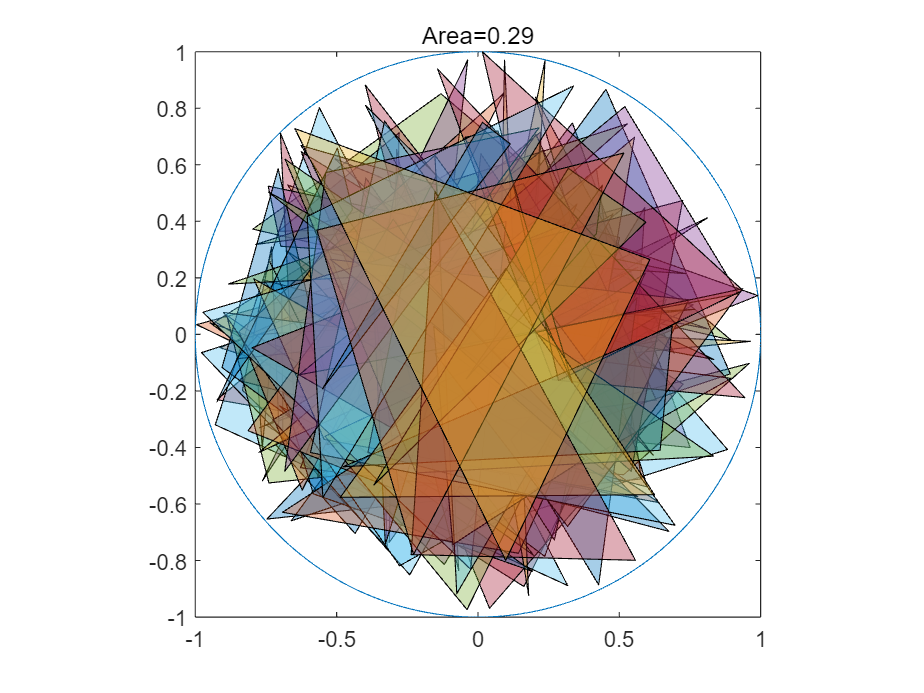

clf
ang=0:0.01:2*pi; 
xp=cos(ang);
yp=sin(ang);
plot(xp,yp);
totalArea = 0;
for k = 1:1e2
    poly = polyshape(X(k,:),Y(k,:));
    hold on
    plot(poly)
    axis equal
    ylim([-1,1])
    xlim([-1,1])
    totalArea = totalArea + sqrt(P(k).*(P(k)-A(k)).*(P(k)-B(k)).*(P(k)-C(k)));
    title(sprintf('Area=%.2f',totalArea/k))
    drawnow
end

The probability of which the outermost points land in [r,r+h]x[0,2pi] is :$3P(r_1\in [r+r+h] and r_2,r_3 \in [0,r])=6r^5h+3r^4h^2$

Let h tends to 0, then the probability denisity of outermost point lands on r is p(r)=$6r^5$.

Now we consider the outermost point P0 is fixed at origin with the circle of radius r being $(x-r)^2+y^2=r^2$. The other two points being $P_1(r_1,\theta_1) \text{ and } P_2(r_2,\theta_2)$ distributed inside the circle C.

Since the area is $\frac{1}{2}r_1r_2\sin(\theta_2-\theta_1)
$, the expected area size should be:


$$I = \frac{1}{2\pi^2 r^4} \int_{-\pi/2}^{\pi/2}\int^{\pi/2}_{\theta_1} \int_{0}^{2r cos\theta_2} \int_{0}^{2r cos\theta_1} r_1^2 r_2^2 sin(\theta_2-\theta_1) \mathrm{d}r_1\mathrm{d}r_2\mathrm{d}\theta_1 \mathrm{d}\theta_2 $$



$$I=\frac{35r^2}{72\pi}$$


Since P1 and P2 are symetrical, Expected area of the shifted triangle should be $\frac{35r^2}{36\pi}$

Now interate r over [0,1], the expected area is:


$$E(A)=\frac{1}{2}I\cdot\int_0^16r^5\cdot r^2\mathrm{d}r=\frac{35}{48\pi}$$


B. L. Burrows & R. F. Talbot (1996) Random triangles, International Journal of Mathematical Education in Science and Technology, 27:2, 253-259, DOI: [10.1080/0020739960270211](https://doi.org/10.1080/0020739960270211)